clear; clc; close all;

features = h5read("features_1.h5", "/DS1");
labels = h5read("labels_1.h5", "/DS1");

features = features_2_12;
labels = labels_2_12;
clear features_2_12 labels_2_12

split_percent = 0.8;
split_idx = split_percent * size(features, 2);
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

Y_Train = categorical(Y_Train);
Y_Test = categorical(Y_Test);

min(X_Train(:, 9))

ans = -0.9892

X_Train = X_Train ./ max(abs(X_Train));
X_Test = X_Test ./ max(abs(X_Test));

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [4032×80000 double]
      Labels: [8    1    7    5    9    4    2    6    6    0    4    3    1    2    6    4    0    8    8    7    0    5    4    5    2    4    6    1    3    7    1    8    7    6    8    9    2    3    6    4    5    3    1    5    3    4    …    ]


dsTest =   MyDataStore with properties:

    Features: [4032×20000 double]
      Labels: [4    0    3    2    1    0    6    0    4    9    2    1    2    8    3    5    6    1    3    5    4    8    2    4    6    3    7    6    3    5    6    3    7    3    2    3    7    5    4    3    8    2    5    7    2    2    …    ]


layers_G1 = [
    featureInputLayer(4032, "Normalization", "none")
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(12)
    softmaxLayer
    classificationLayer
    ]

layers_G1 =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         12 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

layers_G2 = [
    featureInputLayer(4032, "Normalization", "none")
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ]

layers_G2 =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         10 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 3, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 3
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironme

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:12 |        8.59% |       2.5173 |          0.0100 |
|       1 |          50 |       00:00:15 |       94.53% |       0.7831 |          0.0100 |
|       1 |         100 |       00:00:17 |      100.00% |       0.0136 |          0.0100 |
|       1 |         150 |       00:00:20 |       98.44% |       0.0545 |          0.0100 |
|       1 |         200 |       00:00:22 |      100.00% |       0.0079 |          0.0100 |
|       1 |         250 |       00:00:24 |       98.44% |       0.0418 |          0.0100 |
|       1 |         300 |       00:00:27 |       99.22% |       0.

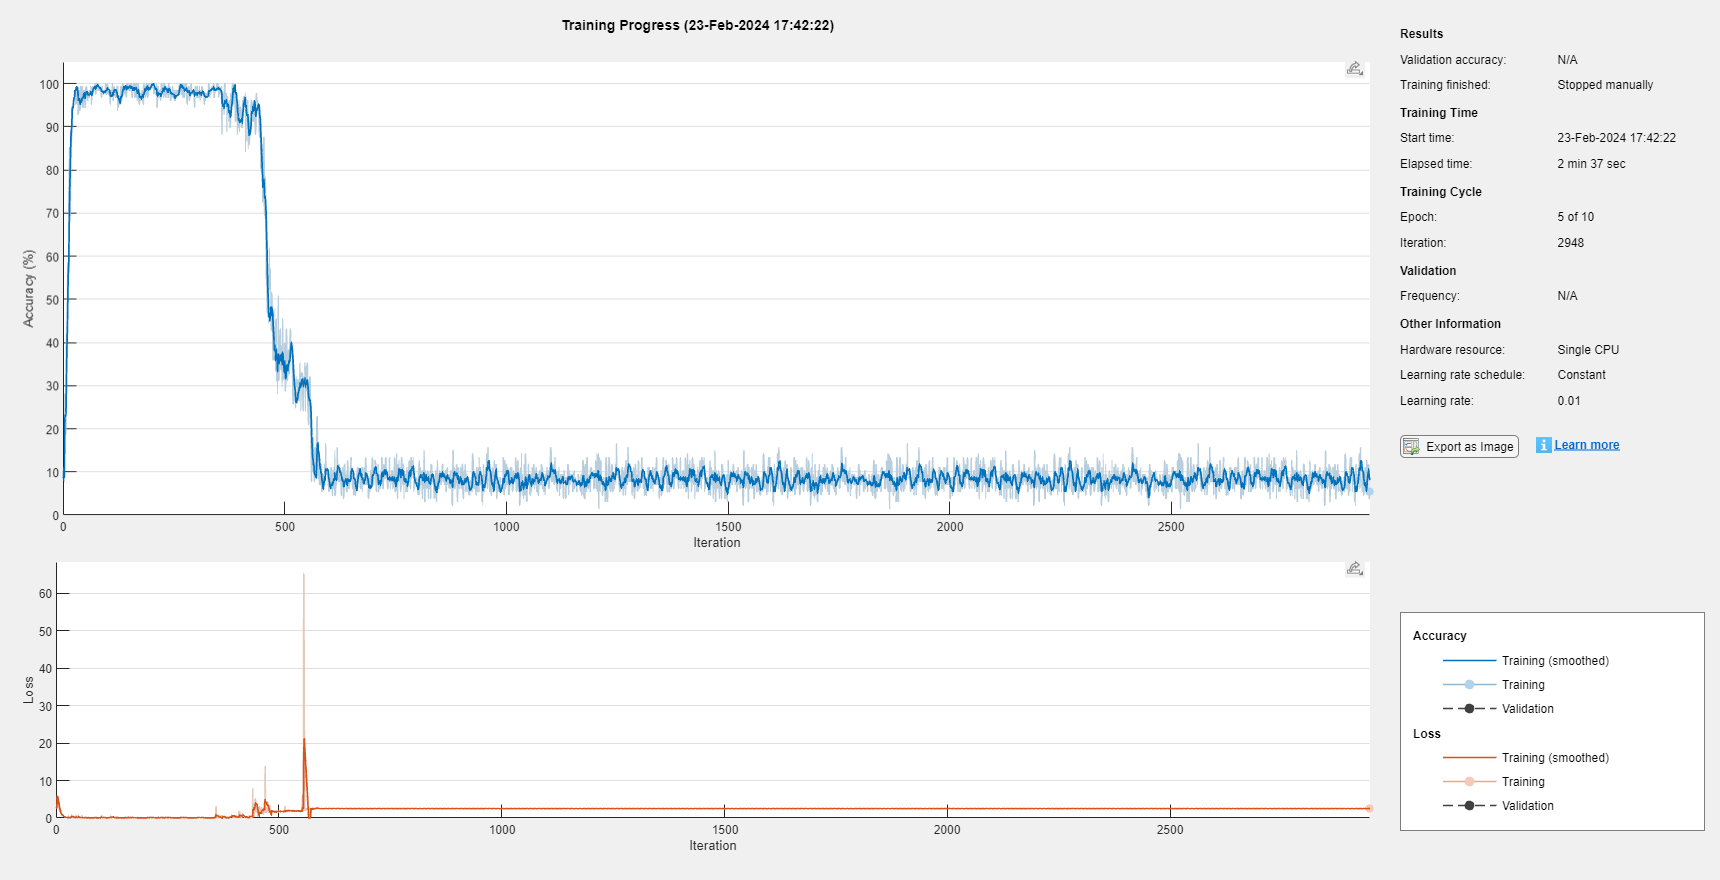

net =   SeriesNetwork with properties:

         Layers: [16×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers_G1, options)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |        7.03% |       2.6340 |          0.0100 |
|       1 |          50 |       00:00:03 |       96.88% |       0.2055 |          0.0100 |
|       1 |         100 |       00:00:05 |       98.44% |       0.0365 |          0.0100 |
|       1 |         150 |       00:00:08 |       93.75% |       0.1096 |          0.0100 |
|       1 |         200 |       00:00:10 |       98.44% |       0.0388 |          0.0100 |
|       1 |         241 |       00:00:12 |       98.44% |       0.0484 |          0.0100 |
|=================================================================

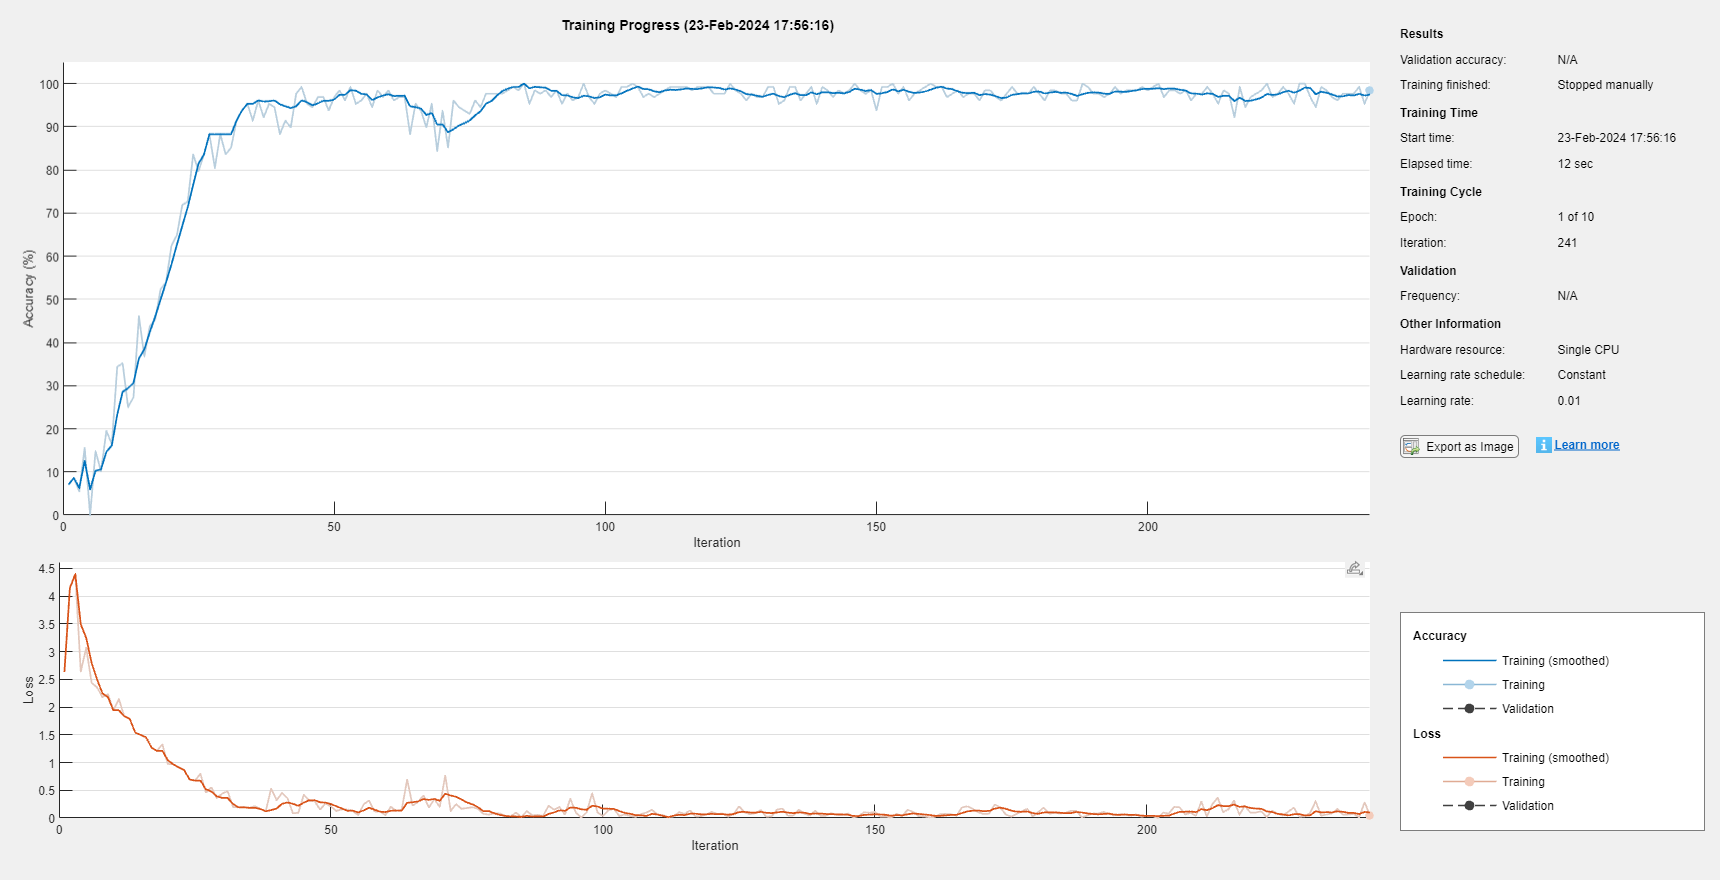

net =   SeriesNetwork with properties:

         Layers: [16×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers_G1, options)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |        3.12% |       2.2786 |          0.0100 |
|       1 |          50 |       00:00:08 |       66.41% |       0.7626 |          0.0100 |
|       1 |         100 |       00:00:10 |       88.28% |       0.4290 |          0.0100 |
|       1 |         150 |       00:00:12 |       95.31% |       0.2599 |          0.0100 |
|       1 |         200 |       00:00:14 |       86.72% |       0.3950 |          0.0100 |
|       1 |         250 |       00:00:16 |       94.53% |       0.1369 |          0.0100 |
|       1 |         300 |       00:00:19 |       90.62% |       0.

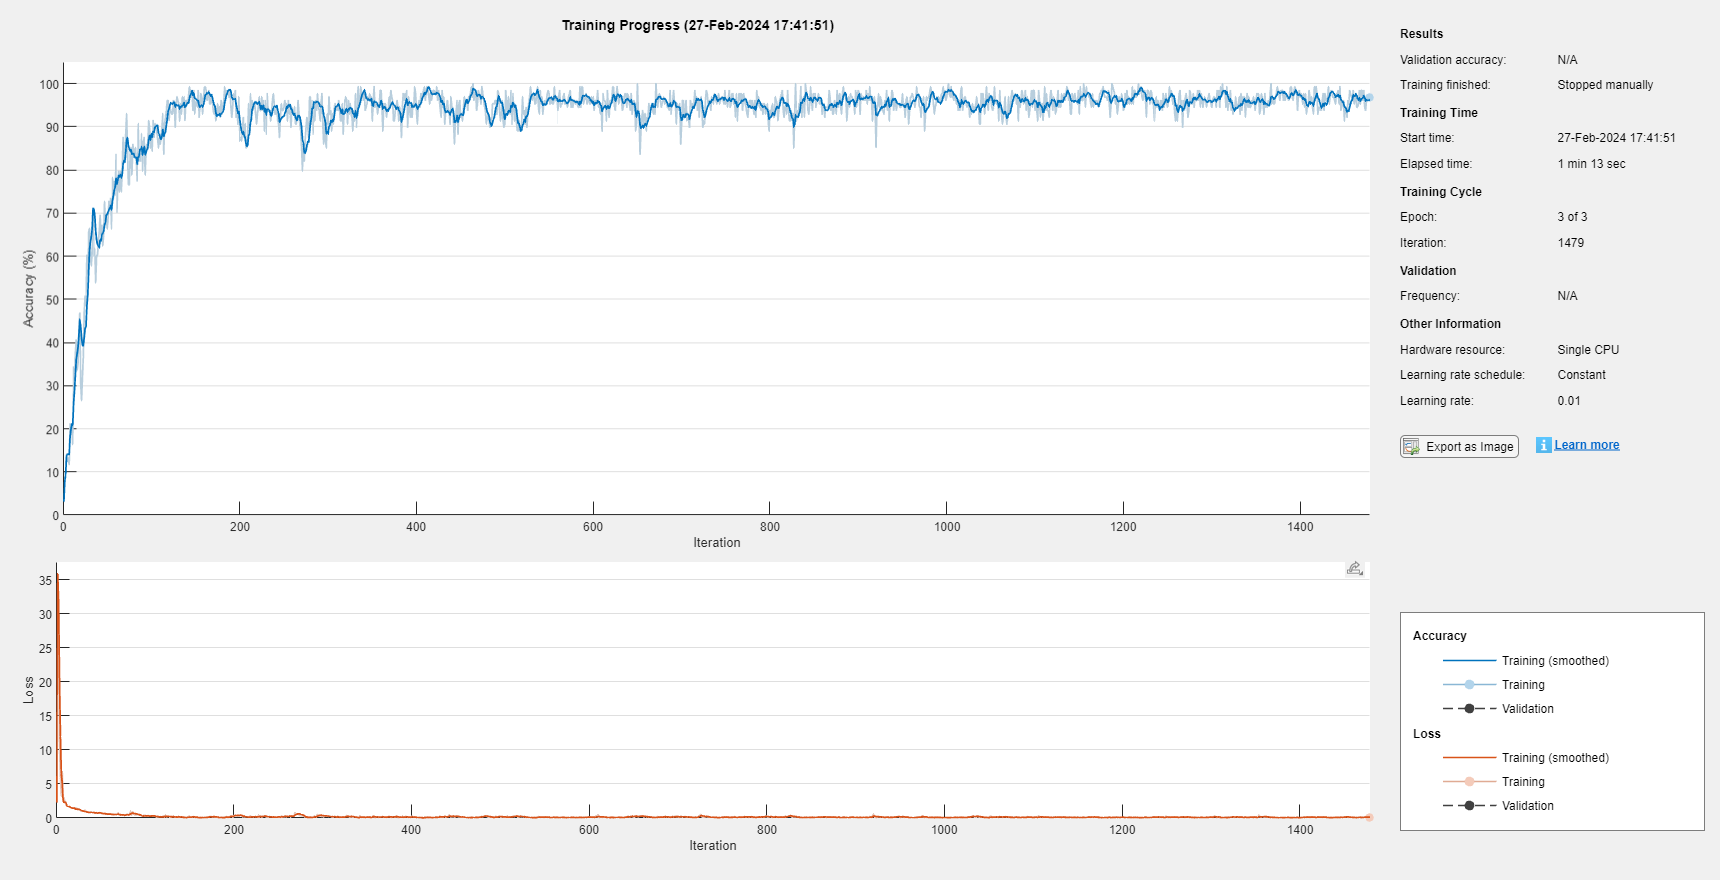

D2_12 =   SeriesNetwork with properties:

         Layers: [16×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


D2_12 = trainNetwork(dsTrain, layers_G2, options)

dsTrain.read()

ans = 1×2 cell array
    {4032×1 double}    {[5]}


YPred = classify(D2_1, dsTest);
YValidation = dsTest.Labels.';
accuracy = sum(YPred==YValidation)/numel(YValidation)

accuracy = 0.9751

# Testing

load D1_Network
load D2_Network

% D2{12} = D2_12

D2 = 1×12 cell array
    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}    {1×1 SeriesNetwork}


YPred = classify(D2{12}, dsTest);
YValidation = dsTest.Labels.';
accuracy = sum(YPred==YValidation)/numel(YValidation)

accuracy = 0.9843

phi_min = 30;
phi_max = 149;
delta_phi = 10;
sensor_locations = 0:63;
M = length(sensor_locations);

doa = rand * (phi_max - phi_min) + phi_min;
rounded_doa = round(doa);

l_h = ceil((rounded_doa - phi_min + 1) / delta_phi);
A = DOA.Array_Manifold(0.5, sensor_locations, doa);
SNR = 10;

R = A * A' + (1 / SNR) * eye(M);

re_R = real(R);
im_R = imag(R);
re_r = zeros((M-1) * M / 2, 1);
im_r = zeros((M-1) * M / 2, 1);

idx2 = 0;
for i = 1:M-1
    idx1 = idx2 + 1;
    idx2 = idx1 + M - i - 1;
    re_r(idx1:idx2) = re_R(i, i+1:M);
    im_r(idx1:idx2) = im_R(i, i+1:M);
end
r = [re_r; im_r];
r = (r - mean(r)) / max(abs(r));

doa

doa = 136.3399

l_h - 1

ans = 10

output1 = classify(D1, r.');
idx1 = double(output1)

idx1 = 11

output2 = classify(D2{idx1}, r.');
idx2 = double(output2)

idx2 = 7

estimated_doa = phi_min + delta_phi * (idx1 - 1) + 1 * (idx2 - 1)

estimated_doa = 136

phi_min = 30;
phi_max = 149;
delta_phi = 10;
sensor_locations = 0:63;
M = length(sensor_locations);
L = 200;

doa = rand * (phi_max - phi_min) + phi_min;
rounded_doa = round(doa);

l_h = ceil((rounded_doa - phi_min + 1) / delta_phi);
A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(1, L);
SNR_dB = 10;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;

% R = A * A' + (1 / SNR) * eye(M);
R = (1 / L) * (y * y');

re_R = real(R);
im_R = imag(R);
re_r = zeros((M-1) * M / 2, 1);
im_r = zeros((M-1) * M / 2, 1);

idx2 = 0;
for i = 1:M-1
    idx1 = idx2 + 1;
    idx2 = idx1 + M - i - 1;
    re_r(idx1:idx2) = re_R(i, i+1:M);
    im_r(idx1:idx2) = im_R(i, i+1:M);
end
r = [re_r; im_r];
r = (r - mean(r)) / max(abs(r));

doa

doa = 33.9512

l_h - 1

ans = 0

output1 = classify(D1, r.');
idx1 = double(output1)

idx1 = 1

output2 = classify(D2{idx1}, r.');
idx2 = double(output2)

idx2 = 5

estimated_doa = phi_min + delta_phi * (idx1 - 1) + 1 * (idx2 - 1)

estimated_doa = 34

phi_min = 30;
phi_max = 149;
delta_phi = 10;
sensor_locations = 0:63;
M = length(sensor_locations);
L = 200;
K = 1;

doa = DOA.DOA_Generate(K, phi_min, phi_max, delta_phi);
rounded_doa = round(doa);

l_h = ceil((rounded_doa - phi_min + 1) / delta_phi);
A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 10;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;

% R = A * A' + (1 / SNR) * eye(M);
R = (1 / L) * (y * y');

r = R2r(R, false);

doa

doa = 113.5865

l_h - 1

ans = 8

output1 = classify(D1, r.');
idx1 = double(output1)

idx1 = 9

output2 = classify(D2{idx1}, r.');
idx2 = double(output2)

idx2 = 5

estimated_doa = phi_min + delta_phi * (idx1 - 1) + 1 * (idx2 - 1)

estimated_doa = 114

phi_min = 30;
phi_max = 149;
delta_phi = 10;
sensor_locations = 0:63;
M = length(sensor_locations);
L = 200;
K = 5;

doa = DOA.DOA_Generate(K, phi_min, phi_max, 1);
rounded_doa = round(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 10;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;

% R = A * A' + (1 / SNR) * eye(M);
R = (1 / L) * (y * y');

r = R2r(R, false);

doa_est = zeros(1, K);
for k = 1:K
    output1 = classify(D1, r.');
    idx1 = double(output1);
    output2 = classify(D2{idx1}, r.');
    idx2 = double(output2);
    estimated_doa = phi_min + delta_phi * (idx1 - 1) + 1 * (idx2 - 1);

    doa_est(k) = estimated_doa;

    A_est = DOA.Array_Manifold(0.5, sensor_locations, estimated_doa);
    R_est = A_est * A_est';
    r_est = R2r(R_est, false);
    r = r - r_est;
end
doa_est = sort(doa_est);

doa

doa =    54.9107   71.3342  106.3035  132.3587  140.2507


doa_est

doa_est =     55    71    90    94   106


function r = R2r(R, normalize)
M = size(R, 1);

re_R = real(R);
im_R = imag(R);
re_r = zeros((M-1) * M / 2, 1);
im_r = zeros((M-1) * M / 2, 1);

idx2 = 0;
for i = 1:M-1
    idx1 = idx2 + 1;
    idx2 = idx1 + M - i - 1;
    re_r(idx1:idx2) = re_R(i, i+1:M);
    im_r(idx1:idx2) = im_R(i, i+1:M);
end
r = [re_r; im_r];
if nargin == 1 || normalize
    r = (r - mean(r)) / max(abs(r));
end
end